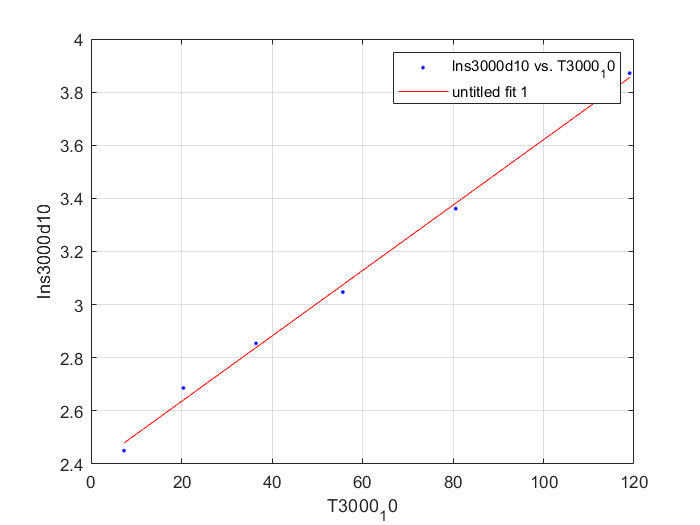

[xData, yData] = prepareCurveData( T3000_10, lns3000d10 );

% Set up fittype and options.
ft = fittype( 'poly1' );

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft );

% Plot fit with data.
figure( 'Name', 'untitled fit 1' );
h = plot( fitresult, xData, yData );
legend( h, 'lns3000d10 vs. T3000_10', 'untitled fit 1', 'Location', 'NorthEast' );
% Label axes
xlabel T3000_10
ylabel lns3000d10
grid on


%Linear model Poly1:
 %    f(x) = p1*x + p2
%Coefficients (with 95% confidence bounds):
 %      p1 =     0.01232  (0.0113, 0.01333)
  %     p2 =       2.389  (2.323, 2.456)

%Goodness of fit:
 % SSE: 0.004609
  %R-square: 0.9965
 % Adjusted R-square: 0.9956
  %RMSE: 0.03394